# Treasure Hunt Game

Welcome to this MATLAB Module designed to teach you how to make a fun treasure hunting game, while learning some core Computer Science concepts along the way. We recommend that you complete our other module: Fundementals of Programming to help better understand the concepts brought up in this module. Hope you enjoy!

The game will look like this when it is finished:

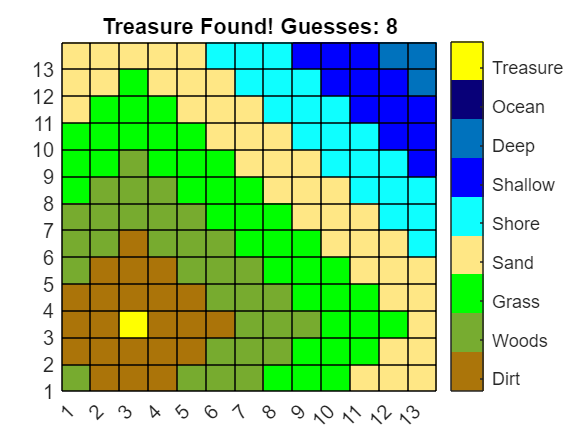

## Section 1: Creating Variables

Variables are a great way to store information to use for later. Some information for this game we want to save includes: the board size, the treasure location, and the numer of guesses made.

First let's start off by making a variable to represent the number of guesses the player has made. I recommend calling this guessNum. We want this variable to be equal to zero because at the start of the game the player will have made zero guesses. 

%Number of guesses the player made
guessNum = 0

guessNum = 0

Next let's move onto the board size. Start by naming your variables. I recommend: columns and rows or length and width. If you prefer, instead you can include only one variable if you want the board to always be a square.

Once your variables have a name, they must equal something. In this case we want them to be an integer that is between 6 and 20.

columns = 15

columns = 15

rows = 15 

rows = 15

If you want to allow the player to change the size of the board to make the game harder or easier, we can add a live control to make that easier for them. You can add a slider to change the value as you wish (Under Control in the Live editor Tab). To edit the slider configurations: Right Click -> Configure controls. Choose a min and max value for the sliders.

columns = 14

columns = 14

rows = 14

rows = 14

You can use old variables to make new ones. Try subtracting one from the columns and rows variable and equate it to a new variable. This variable will be the true boundary of our board. 

limitC = columns - 1

limitC = 13

limitR = rows - 1

limitR = 13

A matlab built in function allows you to easily excute an operation. Functions can be used to generate new variables. The randi function will generate psuedorandom integers. For the input we want to specify the min and the max which will be equal to the bounds of our board. These random values will be equal to a coordinate for our treasure chest. Here is the doc page where you can find more information on this function: [Uniformly distributed pseudorandom integers - MATLAB randi (mathworks.com)](https://www.mathworks.com/help/matlab/ref/randi.html)

treasureX = randi([1 limitC])

treasureX = 9

treasureY = randi([1 limitR])

treasureY = 7

## Working with Matricies

Matlab was originally created to help solve complex linear algebra problems, involving matricies. A matrix is an r x c array of numbers, where r is the number of rows and c is the number of columns. We already specified our row and column height early so now we can use those variables to create our matrix which will represent our entire board or treasure map. 

In order to create our first matrix we want to use another function. One such function we can use is the zeros function. This function creates a matrix that is made up of zeros that is the size of the rows and columns we specify in the input. More information on the zeros function can be found here: [Create array of all zeros - MATLAB zeros (mathworks.com)](https://www.mathworks.com/help/matlab/ref/zeros.html#:~:text=X%20%3D%20zeros(%20sz%20)%20returns,2%2Dby%2D3%20matrix.&text=X%20%3D%20zeros(___%2C%20typename%20)%20returns%20an%20array%20of,%2C%208%2Dbit%20integer%200%20.)

%Creates the blank map
map = zeros(rows, columns)

map =      0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Great! Now we have a matrix that is the correct size we want that is filled with zeros. Now let's take the zeros in the matrix and transform them into NaNs.

NaN stands for Not a Number. The reason we want all the values to be equal to NaN is for the initial board state. Matlab interpts NaN values as white and this is exactly what we want for our empty map. 

We need MATLAB to go through the entire matrix and change any value that is a zero into NaN. There is a neat little trick we can use to do this. Use our matrix of zeros and put soem parentheses next to it. Inside these paretheses we want: (var == 0).

If we have two equal signs, this means that MATLAB is asking a question. MATLAB is asking if the two values are equal to each other. If that statement is true then MATLAB will equate the value to NaN. This statement should be true for our entire matrix. 

map(map == 0) = NaN

map =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


Now we want to use another built-in MATLAB function. This one is called meshgrid. The reasone we are use meshgrid is to map each of the points in our matrix to an x,y coordinate. 

[2-D and 3-D grids - MATLAB meshgrid (mathworks.com)](https://www.mathworks.com/help/matlab/ref/meshgrid.html)

%Creates the colored in Map
[x2,y2] = meshgrid(1:columns,1:rows)

x2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14
     1     2     3     4     5     6     7     8     9    10    11    12    13    14


y2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7     7     7     7     7
     8     8     8     8     8     8     8     8     8     8     8     8     8     8
     9     9     9     9     9     9     9     9     9     9     9     9     9     9
    10    10    10    10    10    10    10    10    10    10    10    10    10    10


Now that we have our board and our treasure location we want to calculate the distance from each coordinate point to our treasure. We can use the Taxicab Metric to calculate the distance between two coordinates points. This external link provides some great insight on how to calculate the Taxicab Metric: [Taxicab Metric -- from Wolfram MathWorld](https://mathworld.wolfram.com/TaxicabMetric.html)

The Taxicab Metric requires us to find the absolute value. There is a built-in MATLAB function that can do this for us called abs. More information on the abs function can be found here: 

[Absolute value and complex magnitude - MATLAB abs (mathworks.com)](https://www.mathworks.com/help/matlab/ref/abs.html)

taxiMatrix = abs(treasureY - y2(:))+ abs(treasureX - x2(:))

taxiMatrix =     14
    13
    12
    11
    10
     9
     8
     9
    10
    11


You may have noticed that the output of our Taxicab formula produced a vector. We need to convert our vector back into a Matrix. In order to do this let's use the reshape function. It takes three inputs, our vector and the rew and column size. More information on the reshape function can be found here: [Reshape array - MATLAB reshape (mathworks.com)](https://www.mathworks.com/help/matlab/ref/reshape.html)

finalMap = reshape(taxiMatrix,rows,columns)

finalMap =     14    13    12    11    10     9     8     7     6     7     8     9    10    11
    13    12    11    10     9     8     7     6     5     6     7     8     9    10
    12    11    10     9     8     7     6     5     4     5     6     7     8     9
    11    10     9     8     7     6     5     4     3     4     5     6     7     8
    10     9     8     7     6     5     4     3     2     3     4     5     6     7
     9     8     7     6     5     4     3     2     1     2     3     4     5     6
     8     7     6     5     4     3     2     1     0     1     2     3     4     5
     9     8     7     6     5     4     3     2     1     2     3     4     5     6
    10     9     8     7     6     5     4     3     2     3     4     5     6     7
    11    10     9     8     7     6     5     4     3     4     5     6     7     8


Now that we have our Matrix filled in, we want to make sure the treasure shows up correctly when we plot it later. You can index into your matrix and change specific values. We want to index to our treasure's location and change it to a really high value. I recommend 500. 

%Treasure is very high values to it shows up correctly
finalMap(treasureY,treasureX) = 500

finalMap =     14    13    12    11    10     9     8     7     6     7     8     9    10    11
    13    12    11    10     9     8     7     6     5     6     7     8     9    10
    12    11    10     9     8     7     6     5     4     5     6     7     8     9
    11    10     9     8     7     6     5     4     3     4     5     6     7     8
    10     9     8     7     6     5     4     3     2     3     4     5     6     7
     9     8     7     6     5     4     3     2     1     2     3     4     5     6
     8     7     6     5     4     3     2     1   500     1     2     3     4     5
     9     8     7     6     5     4     3     2     1     2     3     4     5     6
    10     9     8     7     6     5     4     3     2     3     4     5     6     7
    11    10     9     8     7     6     5     4     3     4     5     6     7     8


The last thing we want to do before setting up our plot is set the colors for our colormap. A colormap is a matrix full of values that will represent how far away you are from the treasure. I chose nine different colors for my colormap. The last colors should represent the treasure.

One of the ways that colors are represent in MATLAB are by their RGB value. RGB stands for Red Green Blue. All possible colors can be created depending on how much Red Green and Blue you put into it.

An option to find the RGB values for the colors you want to use for your color map is to use a built-in MATLAB app called uisetcolor. You can type this into the MATLAB Command Window and the app will pop up and let you pick colors. It will then output the RGB value for you to use. More information on uisetcolor can be found here:

[Open color picker - MATLAB uisetcolor (mathworks.com)](https://www.mathworks.com/help/matlab/ref/uisetcolor.html)

%The colormap for the board with different colors to simulate an island
cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0]

cmap =     0.6706    0.4588    0.0392
    0.4667    0.6745    0.1882
         0    1.0000         0
    1.0000    0.9059    0.5216
    0.0588    1.0000    1.0000
         0         0    1.0000
         0    0.4471    0.7412
    0.0314         0    0.4706
    1.0000    1.0000         0


## Creating Plots and Modifying Them

By now I am sure you are sick of just looking at numbers and matricies and want to start plotting to make something pretty. 

Now that we have our Taxicab matrix all set up, we want to display all the values to start creating our treasure map. Let's use the pcolor function to create a pseudocolor plot of our matrix. A pseudocolor plot displays matrix data as an array of colored cells. More information on the pcolor function can be found here: [Pseudocolor plot - MATLAB pcolor (mathworks.com)](https://www.mathworks.com/help/matlab/ref/pcolor.html)

Let's try running the pcolor function on our finalMap variable first. If you called the function correctly it should look similar to the picture below. They yellow represents the treasure location. Try running the function multiple times and see what happens to the treasure location. 

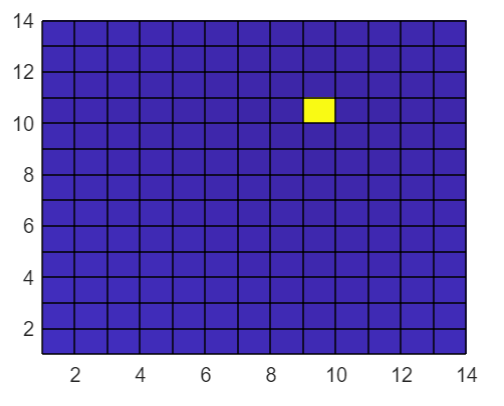

%try calling the pcolor function on the finalMap variable
pcolor(map)

Place holder for later. Skip this section for now.

hold on

[](https://www.mathworks.com/help/matlab/ref/clim.html)

Remember the colormap values that we picked early. Let's use those colors so that our treasure is no longer stranded in the middle of the ocean. If we use the colormap function and input our colormap values from early we should get something like the picture below:

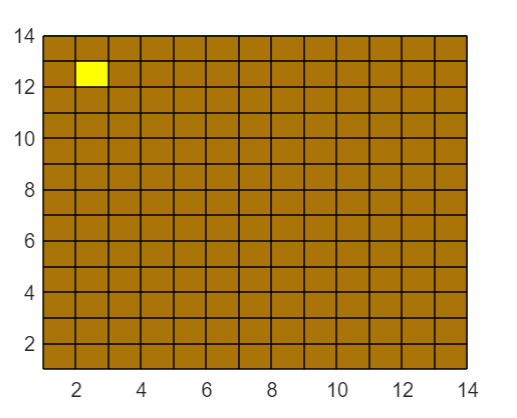

The treasure should now be equal to the last value in your colormap (mine is yellow) and everything else should be equal to the first value in your colormap (mine is brown). More information on the colormap can be found here:

[View and set current colormap - MATLAB colormap (mathworks.com)](https://www.mathworks.com/help/matlab/ref/colormap.html)

colormap(cmap)

I bet you are wondering where all the other colors in our colormap are. Let's include a colorbar to make it easier to see those colors and how they corespond to values on our plot. Also set the colorbar equal to a variable so that we can add to it later. More information on colorbars can be found here:

[Colorbar showing color scale - MATLAB colorbar (mathworks.com)](https://www.mathworks.com/help/matlab/ref/colorbar.html)

 c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 28]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


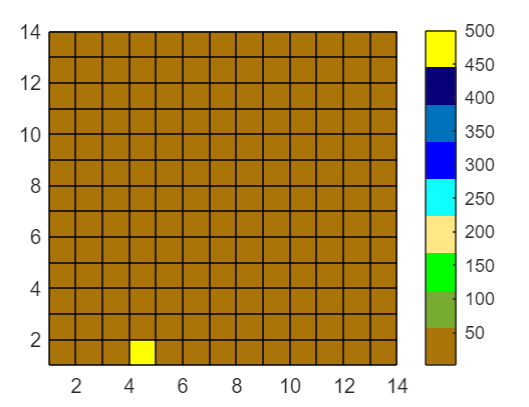

If we look at the colorbar that MATLAB created, it tells us that the upper limit is 500 and the lower limit is 0. If you remember, our Taxicab matrix contains all the distances from the treasure. Since my map is 14 x 14 the furthest away point from the treasure will be around 20ish. 20 is less than 50 so all the values that are not the treasure become brown in our plot. 

In order to change this, we need to use the clim function to change our colormap limits. 

Try changing the upper limit value and see what happens. Try changing the lower limit value and see what happens. For the best results, I recommend setting the upperlimit to rows*2 and the lower limit to 0. Your plot should look something like the below image if you set the limits the same as I did:

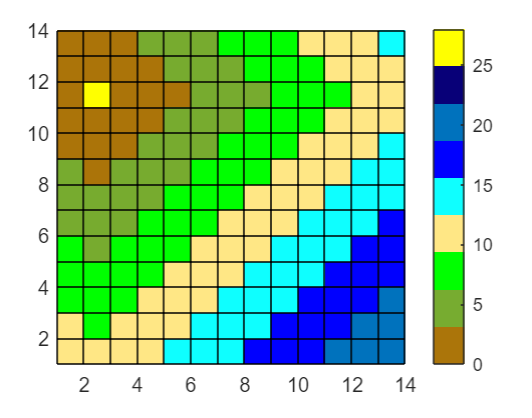

More information on the clim function can be found here:

[Set colormap limits (Renamed from caxis in R2022a) - MATLAB clim (mathworks.com)](https://www.mathworks.com/help/matlab/ref/clim.html)

clim([0 rows*2])

It will make it easier for players to interpet our colorbar if we add labels to it. To do this, we need to use the colorbar variable that we made earlier and access the TickLabels property from it. This can be done like so: var.TickLabels. These were the values I used for my TickLabels: {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean', 'Treasure'}. You are welcome to change them if you like, just make sure the number of Labels is equal to the number of colors you chose. Your colorbar should now look like this if done correctly: 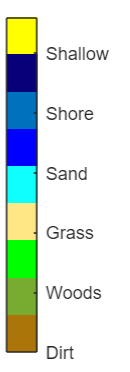

c.TickLabels = {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean', 'Treasure'}

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 28]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


You may have noticed that the Tick Labels in our colorbar do not align correctly. Fortunatley the colorbar variable has a property that can fix this called Ticks. It can be acessed in the following way: var.Ticks.

We set the Ticks property equal to three numbers. The first number is the min, second number is the tick spacing,and the third number is the max.

Try changing the 3 values one at a time and see what happens to the Ticks in your color back. I have provided some min, max, and spacing values that worked for me. The division by 9 is based on the nine colors I chose for the colormap. If you chose more or less, make sure to change the number accordingly. 

min = 1;
spacing = rows*2/9;
max = rows*2;

c.Ticks = min:spacing:max

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 28]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


Now that we have our colorbar all set up, let's make our x and y axis look better. Similar to how we set the Ticks for the colorbar, we can also set Ticks for the x and y axis. There are functions that will let us do this quickly called xticks and yticks. For the input of the function we give it three numbers spaced with a colon. The threen numbers are the min, spacing, and the max. More information on these functions can be found here:

[Set or query x-axis tick values - MATLAB xticks (mathworks.com)](https://www.mathworks.com/help/matlab/ref/xticks.html)

Try playing around with these numbers. When you are done I recomend you set the min to 1, the spacing to 1, and the max to the limitC or limitR value that we made above. Your plot should look like this when done:

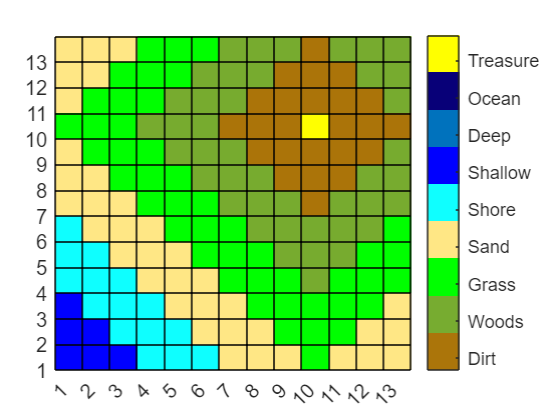

xticks(1:1:limitC)
yticks(1:1:limitR)

We should add a title to help instruct player on what they should do. MATLAB has another built-in function to do just that called title. Just call the title function and the input will take a sting of what you want it to say. Mine I chose to say, "Find the Treasure!". More info on the title function can be found here:

[Add title - MATLAB title (mathworks.com)](https://www.mathworks.com/help/matlab/ref/title.html)

The title should look like this:

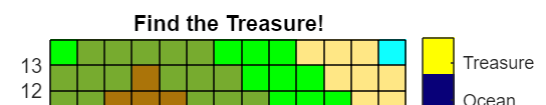

title("Find the Treasure!")

Now before we move onto the next section, go back up to line 23 and change the input in the pcolor function to our NaN matrix. This will make it so our plot is filled with white squares. We were using the Taxicab matrix for learning purposes. Now we want to set it up so someone can play the game and guess where the treasure is. Calling pcolor with the NaN matrix will look like this:

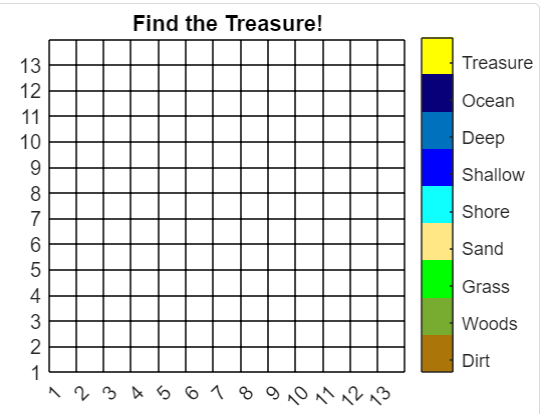

## User Input and If Statements 

When making a game, you will need to gather some kind of input from the user. This could include mouse clicks, button presses, or keyboard strokes. In the case of our treasure hunting game, we want to take in two numers that represents the player's x and y coordinate guess. 

Let's make two new variables for the player's guess. I called my guessX and guessY.

guessX = 1

guessX = 1

guessY = 1

guessY = 1

It is going to get annoying for the user to have to delete and type in a new guess everytime and we want to make sure they are guessing within the bounds of our plot. Let's use another live control to accomplish this. The live crontrol is called Numeric Spinner. We want to right click on is and select Configure Control. There we want to set the label, the min to 1, the max to limit C or R and Run to Nothing. 

guessX = 10

guessX = 10

guessY = 9

guessY = 9

Now that we have the user's guess, we need to show where their guess is by updating it on our plot. To do this we must index into our NaN matrix and change the guess value to the value in our Taxicab matrix. Then we need to call pcolor again on our NaN matrix to update it. I tried the guesses X:6 and Y:4 and it looks something like this:

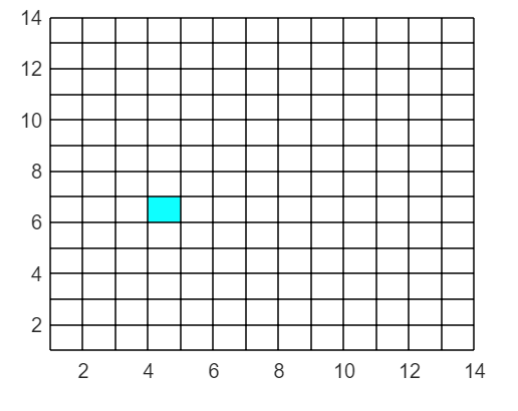

%map(guessX,guessY) = finalMap(guessX,guessY);
%pcolor(map)

Now if you look at my picture above, you will see that my guess is at (4,6) and not (6,4) like I intended. This is because MATLAB matrix indexing works the opposite way of traditional XY grid indexing. Therefore to have the correct guess we need to switch the X and Y guesses for both matricies. Once you swap X and Y the plot will look like this:

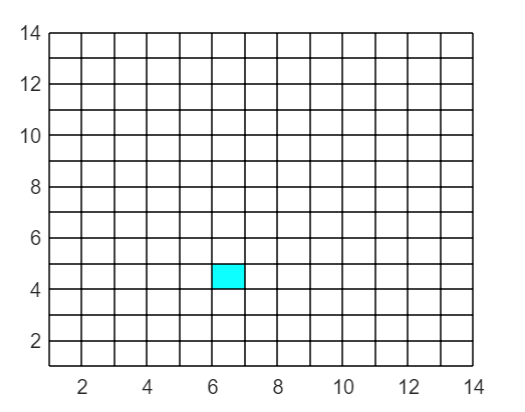

More information on matrix indexing can be found here:

[Matrix Indexing in MATLAB - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html)

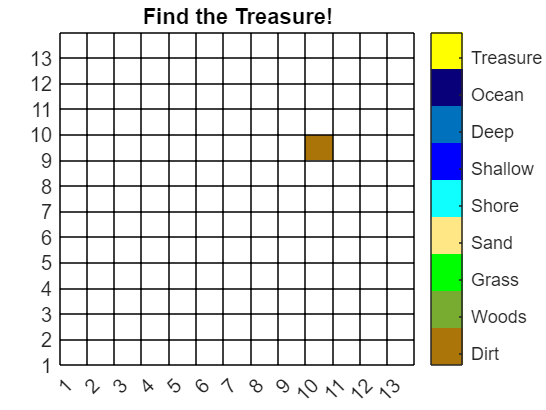

map(guessY,guessX) = finalMap(guessY,guessX);
pcolor(map)

Also you may have noticed that all the beatiful things we added above like the colorbar, title, and extra ticks are all gone. That is because we created a completely new plot. If we want our changes to remain on the same plot we need to go back up to line 24 and type in hold on. This will retain all the changes we added previously. More info on hold on:

[Retain current plot when adding new plots - MATLAB hold (mathworks.com)](https://www.mathworks.com/help/matlab/ref/hold.html)

Your new plot should look like this:

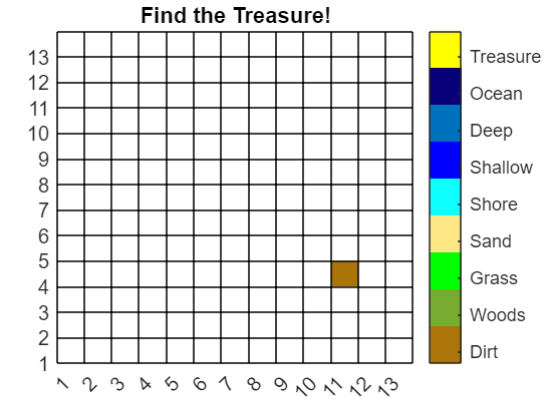

If you go back up to line 39 and 40 where we added our live control, you can change your guess and select Run Section to see many new squares become filled in like so:

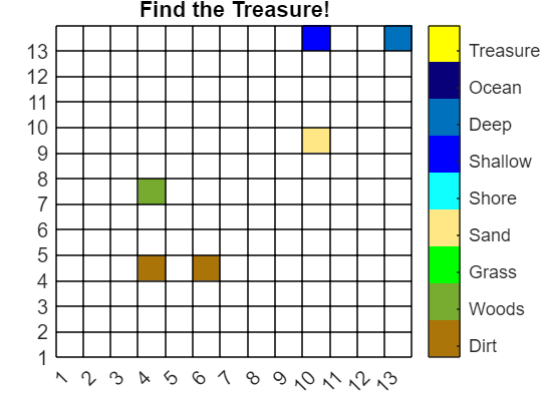

There are a few other things we need to take care of before our game is completely functional. If you click the run button you will see that will automatically put in the guess that is already there. This can be frustrating for the player. To prevent this let's add an if statment. An if statement is a conditional statment that will only exectute a lines of code inside it if the if statement is true. 

Let's use our guessNum variable from above to see if the player has made a guess already. Let's put the guess X and Y live control inside the if statement. In the if statement we want to check if the guessNum is greater than 0. If the guessNum is zero that means we have started the game. 

In its current state, the value of guessNum never changes, so let's add an else statement and increment the value of guessNum inside it so that the game can start. 

if(guessNum < 0)
    guessX = 5;
    guessY = 3;

    guessNum = guessNum + 1;
else
    %Increments the Guess Numbers to start the game
    guessNum = guessNum + 1;
end

I have provided a finalized version of the above code section. Feel free to use this after you finish the Creating and Using Functions section. 

Finalized player interaction section:

% Play Game
%  
% 
% if(guessNum < 0)
%     guessX = 5;
%     guessY = 1;
% 
%     Run function to check guesses
%     playGame(treasureX,treasureY,map,finalMap,guessX,guessY,guessNum)
%     guessNum = guessNum + 1;
% else
%     Increments the Guess Numbers to start the game
%     guessNum = guessNum + 1;
% end

## Creating and Using Functions

We have used many built-in MATLAB functions to build this game, but did you know that you can build your own. It is important to make your own function when you have code that will be executed multiple times with different inputs. 

Try creating your own function that adds 5 to an inputed number and returns that value. 

More info on declaring your own functions can be found here:

[Declare function name, inputs, and outputs - MATLAB function (mathworks.com)](https://www.mathworks.com/help/matlab/ref/function.html)

addFive(3)

function fiveMore = addFive(num)

ans = 8

    fiveMore = num + 5;
end

Notice that we must call the function before its declaration.

I have provided a function we can use to run our game a bit more smoothly. I have provided it below. 

Finalized Function:

function playGame(tX,tY,m,fm,gX,gY,gN)
    
    %If the guess is equal to the treasure location
    if(gX == tX)&&(gY == tY)
        %Fill in the whole grid
        pcolor(fm);
        %Display the new title
        finish = "Treasure Found! Guesses: " + gN;
        title(finish);
    %If the guess is not equal to the treasure
    else
        %Fill in the color of the location the guessed
        m(gY,gX) = fm(gY,gX);
        pcolor(m);
        
        %Display hint and guess number
        help = "You are " + string(fm(gY,gX)) + " away from the treasure.";
        guess = "Guess: " + gN;
        disp(help);
        disp(guess);
        disp("Guess again!");
        
    end
end